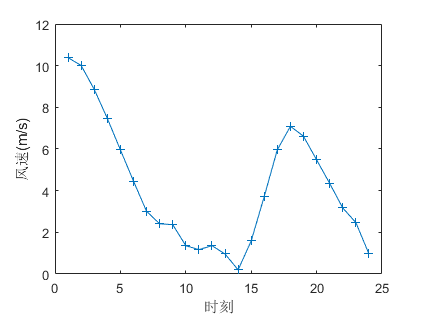

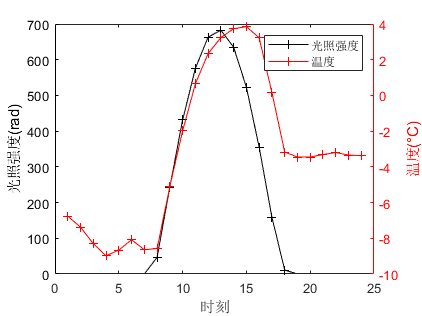

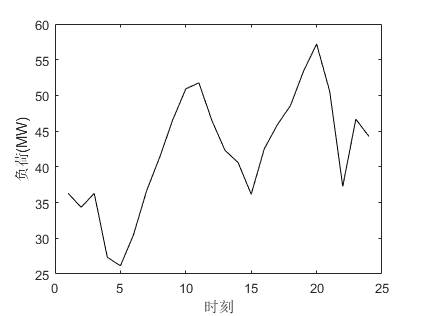

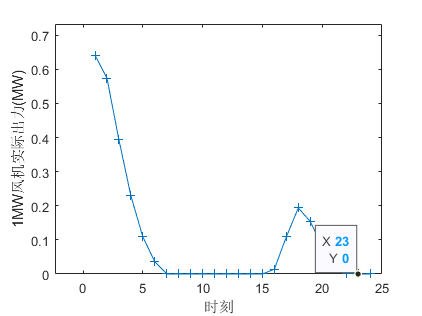

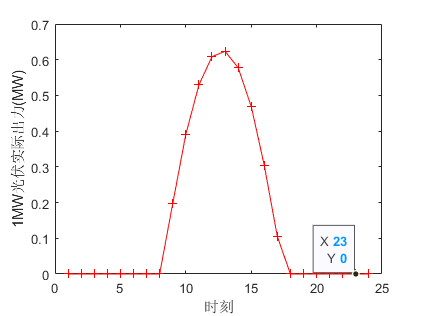

[p_wt_1mw,p_pv_1mw,load] = wind_pv_load();

## 优化开始

%定义 决策变量
wt_cap = sdpvar(1,1,'full'); %风电装机容量 MW
pv_cap = sdpvar(1,1,'full'); %光伏装机容量 MW
 
%描述 约束
C = [p_wt_1mw*wt_cap + pv_cap*p_pv_1mw >= load];
C = [C, wt_cap>=0];
C = [C, pv_cap>=0];

%优化目标
c_wt = 0.1; % 风机运行成本 $/MWh
c_pv = 710 *1000; % 光伏装机成本 $/MW

obj = c_wt * wt_cap + c_pv * pv_cap;

% 优化求解器调用
ops = sdpsettings('solver' ,'cplex'); %采用cplex求解器
result = optimize(C,obj,ops);

Matlab Toolbox parameter "Display" found.


Version identifier: 12.10.0.0 | 2019-11-26 | 843d4de2ae
CPXPARAM_MIP_Display                             1
Infeasibility row 'c8':  0 <= -41.3365.
Presolve time = 0.03 sec. (0.00 ticks)


%验证想法的正确性，从而确保并非是代码出问题
p_wt_1mw_2 = p_wt_1mw +0.01;
%清空之前的优化模型
yalmip('clear')
%定义 决策变量
wt_cap = sdpvar(1,1,'full');
pv_cap = sdpvar(1,1,'full');

%描述 约束
C = [p_wt_1mw_2 *wt_cap + pv_cap*p_pv_1mw >= load];
C = [C, wt_cap>=0];
C = [C, pv_cap>=0];
%优化目标
c_wt = 1400 *1000; % 风机装机成本 $/MW
c_pv = 710 *1000; % 光伏装机成本 $/MW
obj = c_wt * wt_cap + c_pv * pv_cap;

% 优化工具箱
ops = sdpsettings('solver' ,'cplex'); %采用cplex求解器
result = optimize(C,obj,ops);

Matlab Toolbox parameter "Display" found.


Version identifier: 12.10.0.0 | 2019-11-26 | 843d4de2ae
CPXPARAM_MIP_Display                             1
Tried aggregator 1 time.
LP Presolve eliminated 26 rows and 2 columns.
All rows and columns eliminated.
Presolve time = 0.00 sec. (0.01 ticks)


%因此，原问题没有可行解，故我们需要引入储能设备
%储能参数 
% S_0为0.3倍装机容量
% S_min为0.1倍装机容量
% S_max为0.9倍装机容量
tau = 0.1; %设备功率-容量比为0.1
yita = 0.95; %储释能效率均为0.95
beta = 0.001; %储能自损耗效率为1小时损耗现有储能量的0.1%

%清空之前的优化模型
yalmip('clear')
%定义 决策变量
wt_cap = sdpvar(1,1,'full'); %风机装机容量 MW
pv_cap = sdpvar(1,1,'full'); %光伏装机容量 MW
ba_cap = sdpvar(1,1,'full'); %电池装机容量 MWh
p_c = sdpvar(24,1,'full'); %电池实时储能功率 MW
p_d = sdpvar(24,1,'full'); %电池实时释能功率 MW
S = sdpvar(24,1,'full'); %电池实时储能量 MWh
u_c = binvar(24,1,'full'); %电池实时储能状态
u_d = binvar(24,1,'full'); %电池实时释能状态

%描述 约束
C = [p_wt_1mw *wt_cap + pv_cap*p_pv_1mw + p_d - p_c >= load];
C = [C, S(1,1) == 0.3*ba_cap*(1-beta) + p_c(1,1)*yita - p_d(1,1)/yita];
for i = 2:24
    C = [C, S(i,1) == S(i-1,1)*(1-beta) + p_c(i,1)*yita - p_d(i,1)/yita];
end
C = [C, S >= 0.1*ba_cap];
C = [C, S <= 0.9*ba_cap];
C = [C, S(24,1) >= 0.3*ba_cap];

C = [C, p_c >= 0];
C = [C, p_c <= ba_cap*tau];
C = [C, p_c <= u_c * 10^5];

C = [C, p_d >= 0];
C = [C, p_d <= ba_cap*tau];
C = [C, p_d <= u_d * 10^5];

C = [C, u_d + u_c == 1];

C = [C, wt_cap>=0];
C = [C, pv_cap>=0];
C = [C, ba_cap>=0];
%优化目标
c_wt = 1400 *1000; % 风机装机成本 $/MW
c_pv = 710 *1000; % 光伏装机成本 $/MW
c_bat = 1000 * 1000; % 电池装机成本 $/MWh
obj = c_wt * wt_cap + c_pv * pv_cap + c_bat*ba_cap;

% 优化工具箱
ops = sdpsettings('solver' ,'cplex'); %采用cplex求解器
result = optimize(C,obj,ops);

Matlab Toolbox parameter "Display" found.


Version identifier: 12.10.0.0 | 2019-11-26 | 843d4de2ae
CPXPARAM_MIP_Display                             1
Tried aggregator 2 times.
MIP Presolve eliminated 66 rows and 9 columns.
Aggregator did 24 substitutions.
Reduced MIP has 178 rows, 90 columns, and 432 nonzeros.
Reduced MIP has 21 binaries, 0 generals, 0 SOSs, and 0 indicators.
Presolve time = 0.02 sec. (0.48 ticks)
Probing time = 0.00 sec. (0.01 ticks)
Tried aggregator 1 time.
Detecting symmetries...
Reduced MIP has 178 rows, 90 columns, and 432 nonzeros.
Reduced MIP has 21 binaries, 0 generals, 0 SOSs, and 0 indicators.
Presolve time = 0.00 sec. (0.30 ticks)
Probing time = 0.00 sec. (0.01 ticks)
MIP emphasis: balance optimality and feasibility.
MIP search method: dynamic search.
Parallel mode: deterministic, using up to 20 threads.

Node log . . .
Best integer =   1.000761e+12  Node =       0  Best node =   4.668065e+08
Best integer =   3.226654e+11  Node =       0  Best node =   4.668065e+08
Best integer =   8.568271e+08  Node

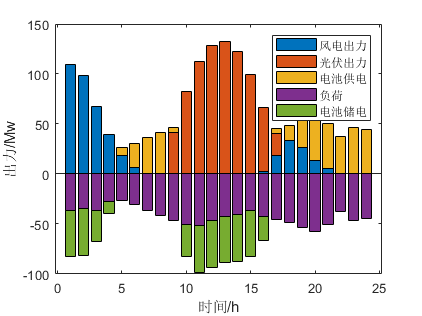

%查看优化结果具体值
wt_cap = value(wt_cap); %风机装机容量 MW
pv_cap = value(pv_cap); %光伏装机容量 MW
ba_cap = value(ba_cap); %电池装机容量 MW
p_c = value(p_c); %电池实时储能功率 MW
p_d = value(p_d); %电池实时释能功率 MW
S = value(S); %电池实时储能量 MWh
u_c = value(u_c); %电池实时储能状态
u_d = value(u_d); %电池实时释能状态
P_wind = wt_cap * p_wt_1mw; %风机出力
P_pv = pv_cap*p_pv_1mw; %光伏出力

%画图 电平衡
figure('Name','电平衡')
power_output = [P_wind,P_pv,p_d];
power_input = [-load,-p_c];
bar(power_output,'stacked')
hold on 
bar(power_input,'stacked')
legend('风电出力','光伏出力','电池供电','负荷','电池储电')
ylabel('出力/Mw')
xlabel('时间/h')

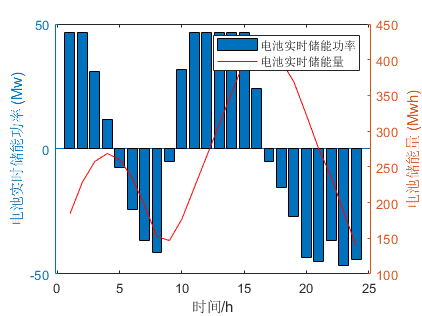


%画图 电池状态
figure('Name','电储能SOC状态')
yyaxis left
h1 = bar(p_c,'stacked');
hold on 
h2 = bar(-p_d,'stacked');
ylabel('电池实时储能功率 (Mw)')
yyaxis right
h3 = plot(S,'r');
ylabel('电池储能量 (Mwh)')
xlabel('时间/h')

legend([h1,h3],'电池实时储能功率','电池实时储能量')